# 1. Presentacion

Estudiamos la conduccion estacionaria en una placa rectangular idealizada. CPU y GPU son regiones con generacion uniforme, no componentes reales. La ecuacion es Laplaciano(T) + q'''/k = 0, con T=Tb en el borde.

## 2. Parametros iniciales

Dimensiones y propiedades estan en metros, watts y W/(m K). La malla base tiene 49 x 33 nodos; la frontera se fija a 25 grados C. Las fuentes usan 12 W para CPU y 18 W para GPU. Cambie solo modo_completo para ejecutar los estudios largos.

modo_completo=false;

% Obtenemos la carpeta de este Live Script para que funcione desde cualquier
% carpeta actual de MATLAB. El fallback permite ejecutar el archivo .m desde
% la raiz del repositorio sin depender del editor.
ruta_laboratorio='';
try
    archivo_activo=matlab.desktop.editor.getActiveFilename();
    if ~isempty(archivo_activo) && isfile(archivo_activo)
        carpeta_activa=fileparts(archivo_activo);
        if isfile(fullfile(carpeta_activa,'ejecutar_proyecto.m')) && ...
                isfolder(fullfile(carpeta_activa,'matlab'))
            ruta_laboratorio=carpeta_activa;
        elseif isfile(fullfile(carpeta_activa,'simulacion','ejecutar_proyecto.m'))
            ruta_laboratorio=fullfile(carpeta_activa,'simulacion');
        end
    end
catch
    % En MATLAB sin escritorio se usa la carpeta actual y sus carpetas padre.
end
if isempty(ruta_laboratorio)
    ruta_busqueda=pwd;
    for nivel=1:8
        if isfile(fullfile(ruta_busqueda,'simulacion','ejecutar_proyecto.m'))
            ruta_laboratorio=fullfile(ruta_busqueda,'simulacion');
            break
        elseif isfile(fullfile(ruta_busqueda,'ejecutar_proyecto.m')) && ...
                isfolder(fullfile(ruta_busqueda,'matlab'))
            ruta_laboratorio=ruta_busqueda;
            break
        end
        ruta_padre=fileparts(ruta_busqueda);
        if strcmp(ruta_padre,ruta_busqueda), break; end
        ruta_busqueda=ruta_padre;
    end
end
assert(~isempty(ruta_laboratorio), ...
    ['No se encontro el laboratorio. Abra el archivo 00_Proyecto_Principal.mlx ' ...
     'del repositorio y vuelva a presionar Run.']);
addpath(ruta_laboratorio);
addpath(fullfile(ruta_laboratorio,'matlab'));
cfg=planteamiento_modelo();
disp(cfg)

                     Lx: 0.2400
                     Ly: 0.1600
              thickness: 0.0020
                      k: 50
                     Tb: 25
                    cpu: [1×1 struct]
                    gpu: [1×1 struct]
                  grids: [4×2 double]
           baselineGrid: [49 33]
              tolerance: 1.0000e-08
          maxIterations: 200000
     initialTemperature: 25
    checkpointFractions: [0.0100 0.1000 0.5000 1]
            assumptions: {'Homogeneous isotropic plate'  'Steady two-dimensional conduction'  'Constant conductivity'  'Uniform rectangular heat sources'  'Fixed boundary temperature'}



## 3. Diferencias Finitas

Las diferencias centrales aproximan las segundas derivadas. En una malla uniforme: T(i,j) es un cuarto de la suma de los cuatro vecinos y q'''*h^2/k. Al reunir las ecuaciones interiores se obtiene A*T=b. Las temperaturas de borde conocidas se trasladan al vector b.

## 4. Gauss-Seidel

Con la convencion del curso A=D-L-U: (D-L)*T_nueva = U*T_anterior + b. El laboratorio conserva la version literal del profesor en matlab/gausseidel_profesor.m. El calculo principal usa la misma recurrencia mediante una resolucion triangular dispersa, sin formar una inversa. Se registra el error relativo entre iteraciones y el residuo relativo.

## 5. Gradiente Conjugado

Para una matriz simetrica definida positiva, CG actualiza x, el residuo r y la direccion p con productos dispersos. La implementacion propia esta en matlab/metodo_gradiente_conjugado.m; no se usa pcg.

## 6. Comparacion

Ambos metodos resuelven la misma matriz, vector y condicion inicial. Tambien se compara con el sistema disperso directo de MATLAB.

## 7. Graficas

MATLAB crea mapas termicos, superficie, residuos, aproximaciones y sensibilidad de temperatura frente a potencia.

## 8. Refinamiento espacial y validacion

El modo rapido comprueba simetria, definitud positiva y conservacion de potencia. El modo completo ejecuta refinamiento, sensibilidad extendida, estadisticas de tiempo y pruebas numericas adicionales.

Malla 49 x 33 nodos, 1457 incognitas; dx=0.005 m, dy=0.005 m
Potencia integrada: CPU 12 W; GPU 18 W
Equivalencia GS en ejemplo pequeno: 7.67e-13
           metodo           iteraciones    residuo_relativo    temperatura_maxima_C    error_iterativo_GS
    ____________________    ___________    ________________    ____________________    __________________

    "Directa dispersa"            1           3.6867e-15              77.759                      NaN    
    "Gauss-Seidel"             2145            9.942e-09              77.759               1.0497e-09    
    "Conjugate Gradient"        127           9.2837e-09              77.759                      NaN    

Residuo GS 9.94e-09, error de iteracion 1.05e-09 (2145 iteraciones)
Residuo CG 9.28e-09 (127 iteraciones)
Tmax 77.759239 C; tiempo medido de los solucionadores 0.288 s
Tiempo total del modo rapido, incluidas figuras: 61.71 s

Modo completo: se ejecutan refinamiento, sensibilidad extendida y pruebas.
                      

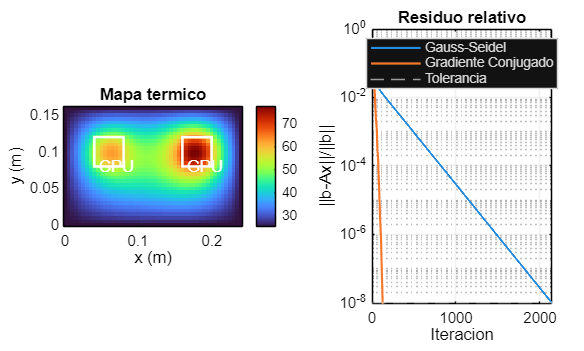

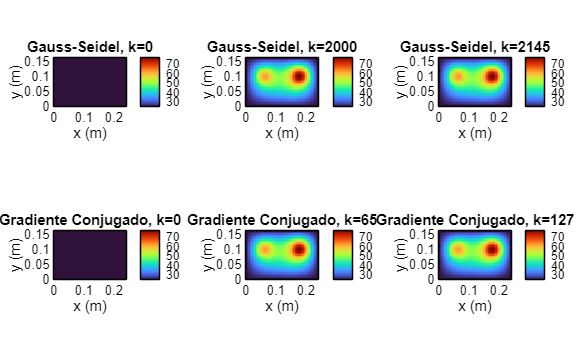

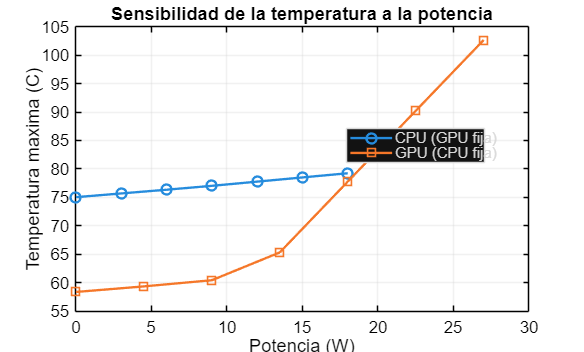

resultado=ejecutar_proyecto(modo_completo);